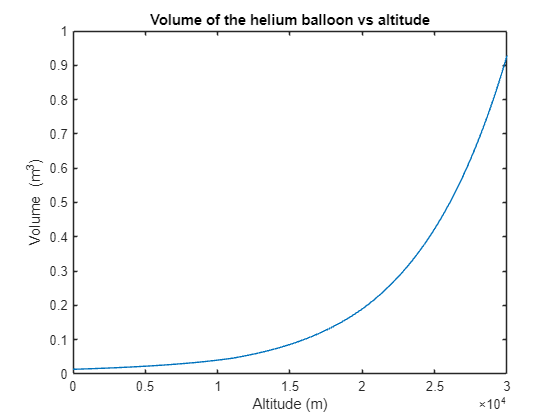

clear;
clc;
close all;

%{
    Water Discplacement:
    Height:           0.095m
    Length: 19.5in  = 0.501m
    Width: 9.75in   = 0.251m
%}

discplaced = Block(0.501, 0.251, 0.095);

%{
    Balloon Masses:
    Substrate mass:        9.553 
    Fixture mass:          1.33
    Fluid mass:            1.723
    Neutral Buoyancy mass: 1.8
%}

balloon1 = Balloon(discplaced.volume, 9.553, 1.33, 1.723, 1.8);
air = Fluid(28.96, .287);
helium = Fluid(4, 2.0769);

% buoyancy = air.buoyancy(balloon1.volume, 294.817, 84)
% 
% buoyancy - balloon1.mass
% 

heights = linspace(0, 30000, 500);
[T,a,P,rho] = atmoscoesa(heights);

kPa = P./1000;
numerator = balloon1.mass;
denom = ((kPa./(air.ideal_constant.*T)) - kPa./(helium.ideal_constant.*T));

V = balloon1.mass./denom;

plot(heights, V);
xlabel("Altitude (m)");
ylabel("Volume (m^3)");
title("Volume of the helium balloon vs altitude");
print("helium", "-dpng", "-r300")

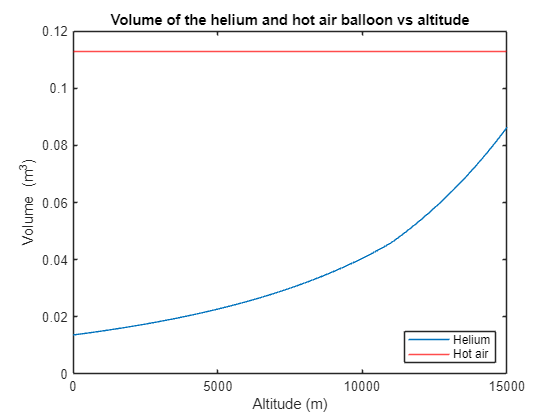


hot_air_volume = 0.113; % m^3
heights1 = linspace(0, 15000, 500);
[T1,a1,P1,rho1] = atmoscoesa(heights1);

kPa1 = P1./1000;
numerator = balloon1.mass;
denom = ((kPa1./(air.ideal_constant.*T1)) - kPa1./(helium.ideal_constant.*T1));

V1 = balloon1.mass./denom;

plot(heights1, V1);
hold on;
yline(hot_air_volume, 'r');
xlabel("Altitude (m)");
ylabel("Volume (m^3)");
legend('Helium','Hot air', 'Location', 'southeast')
title("Volume of the helium and hot air balloon vs altitude");
print("helium_hotair", "-dpng", "-r300")